%% Two-DoF Planar Robot Position Control
% File: two_dof_planar_robot_position_control.m

%% Homework example
% Clean up routine to remove variables from your workspace
clear all;
close all;

%% Initialize the DQ Robotics namespace
include_namespace_dq

%% Robot Parameters
l1 = 1.0;  % Link 1 length (m)
l2 = 1.0;  % Link 2 length (m)

fprintf('Two-DoF Planar Robot Position Control\n');

Two-DoF Planar Robot Position Control


fprintf('Link lengths: l1 = %.2f m, l2 = %.2f m\n\n', l1, l2);

Link lengths: l1 = 1.00 m, l2 = 1.00 m




%% Initial Configuration
theta1_0 = 0;
theta2_0 = pi/2;

fprintf('Initial configuration:\n');

Initial configuration:


fprintf('  theta1(0) = %.4f rad (%.2f deg)\n', theta1_0, rad2deg(theta1_0));

  theta1(0) = 0.0000 rad (0.00 deg)


fprintf('  theta2(0) = %.4f rad (%.2f deg)\n', theta2_0, rad2deg(theta2_0));

  theta2(0) = 1.5708 rad (90.00 deg)



% Initial position
x_init = l1 * cos(theta1_0) + l2 * cos(theta1_0 + theta2_0);
y_init = l1 * sin(theta1_0) + l2 * sin(theta1_0 + theta2_0);
fprintf('  Initial position: [%.4f, %.4f]\n', x_init, y_init);

  Initial position: [1.0000, 1.0000]



%% Desired Position
p_desired = [0; 2];
fprintf('\nDesired position: t_d = [%.4f, %.4f]\n\n', p_desired(1), p_desired(2));


Desired position: t_d = [0.0000, 2.0000]




%% Controller Parameters
K_p = 5.0;
lambda = 0.05;
dt = 0.01;
t_final = 5.0;
time = 0:dt:t_final;
num_steps = length(time);
epsilon = 0.01;

%% Initialize Storage
theta1_history = zeros(1, num_steps);
theta2_history = zeros(1, num_steps);
x_history = zeros(1, num_steps);
y_history = zeros(1, num_steps);
error_history = zeros(1, num_steps);

theta1 = theta1_0;
theta2 = theta2_0;

%% Control Loop
fprintf('Running control simulation...\n');

Running control simulation...



for i = 1:num_steps
    % Forward kinematics
    x_current = l1 * cos(theta1) + l2 * cos(theta1 + theta2);
    y_current = l1 * sin(theta1) + l2 * sin(theta1 + theta2);
    p_current = [x_current; y_current];
    
    % Position error
    error = p_desired - p_current;
    error_norm = norm(error);
    
    % Store history
    theta1_history(i) = theta1;
    theta2_history(i) = theta2;
    x_history(i) = x_current;
    y_history(i) = y_current;
    error_history(i) = error_norm;
    
    % Check convergence
    if error_norm < epsilon
        fprintf('Converged at t = %.2f seconds\n', time(i));
        theta1_history = theta1_history(1:i);
        theta2_history = theta2_history(1:i);
        x_history = x_history(1:i);
        y_history = y_history(1:i);
        error_history = error_history(1:i);
        time = time(1:i);
        break;
    end
    
    % Translation Jacobian
    J = [-l1*sin(theta1) - l2*sin(theta1+theta2), -l2*sin(theta1+theta2);
          l1*cos(theta1) + l2*cos(theta1+theta2),  l2*cos(theta1+theta2)];
    
    % Damped pseudoinverse
    J_pinv = J' / (J*J' + lambda^2*eye(2));
    
    % Control law
    theta_dot = J_pinv * (K_p * error);
    
    % Update joint angles
    theta1 = theta1 + theta_dot(1) * dt;
    theta2 = theta2 + theta_dot(2) * dt;
end

Converged at t = 1.02 seconds



fprintf('Simulation complete\n\n');

Simulation complete




%% Final Results
fprintf('Final Results:\n');

Final Results:


fprintf('  theta1 = %.4f rad (%.2f deg)\n', theta1, rad2deg(theta1));

  theta1 = 1.4767 rad (84.61 deg)


fprintf('  theta2 = %.4f rad (%.2f deg)\n', theta2, rad2deg(theta2));

  theta2 = 0.1830 rad (10.49 deg)


fprintf('  Final position: [%.4f, %.4f]\n', x_history(end), y_history(end));

  Final position: [0.0052, 1.9916]


fprintf('  Final error: %.6f m\n', error_history(end));

  Final error: 0.009870 m


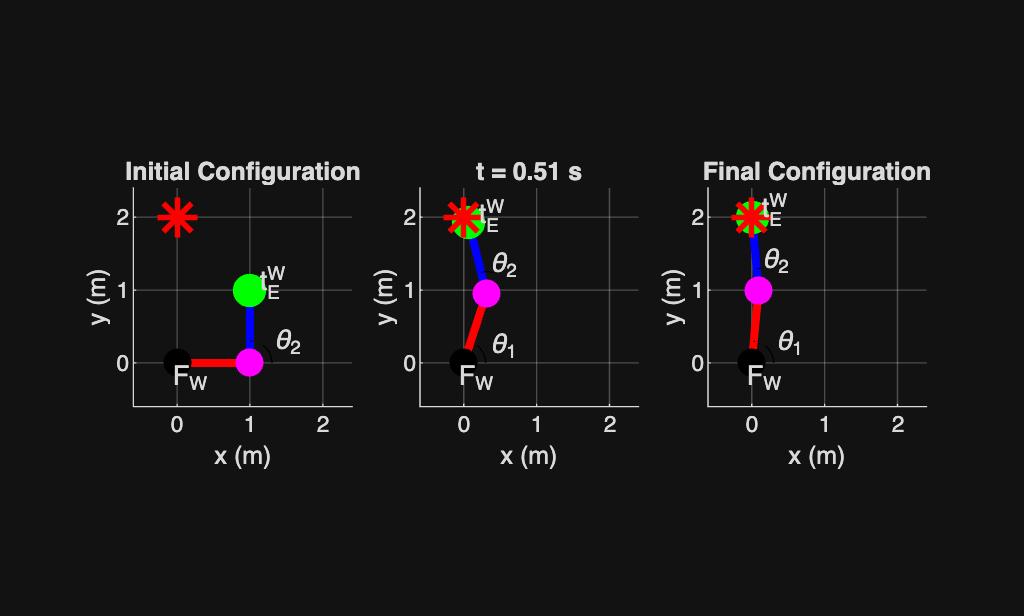


%% Plotting
% Figure 1: Robot configurations
figure('Name', 'Robot Configuration');

subplot(1, 3, 1);
plot_robot(l1, l2, theta1_0, theta2_0, p_desired);
title('Initial Configuration');

subplot(1, 3, 2);
mid = min(round(length(time)/2), length(theta1_history));
plot_robot(l1, l2, theta1_history(mid), theta2_history(mid), p_desired);
title(sprintf('t = %.2f s', time(mid)));

subplot(1, 3, 3);
plot_robot(l1, l2, theta1_history(end), theta2_history(end), p_desired);
title('Final Configuration');

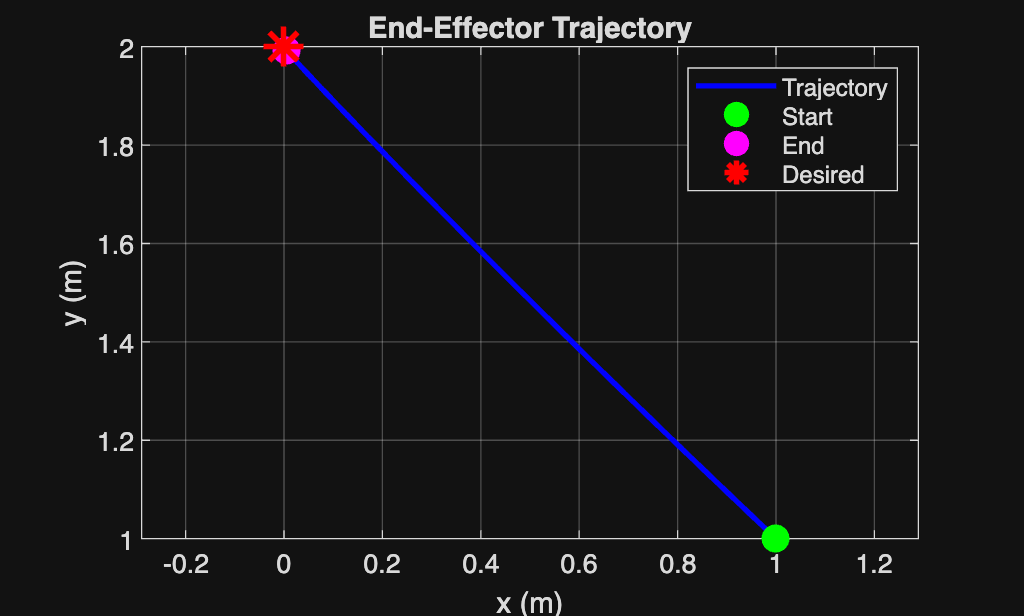


% Figure 2: End-effector trajectory
figure('Name', 'End-Effector Trajectory');
plot(x_history, y_history, 'b-', 'LineWidth', 2);
hold on;
plot(x_history(1), y_history(1), 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
plot(x_history(end), y_history(end), 'mo', 'MarkerSize', 10, 'MarkerFaceColor', 'm');
plot(p_desired(1), p_desired(2), 'r*', 'MarkerSize', 15, 'LineWidth', 2);
grid on; axis equal;
xlabel('x (m)'); ylabel('y (m)');
title('End-Effector Trajectory');
legend('Trajectory', 'Start', 'End', 'Desired');
hold off;

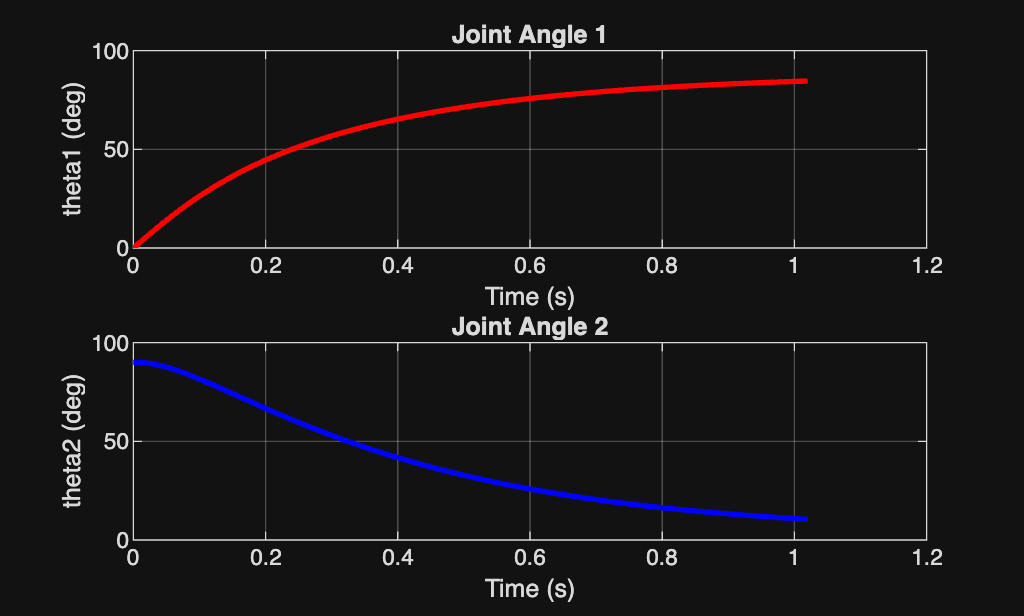


% Figure 3: Joint angles
figure('Name', 'Joint Angles');
subplot(2, 1, 1);
plot(time, rad2deg(theta1_history), 'r-', 'LineWidth', 2);
grid on;
xlabel('Time (s)'); ylabel('theta1 (deg)');
title('Joint Angle 1');

subplot(2, 1, 2);
plot(time, rad2deg(theta2_history), 'b-', 'LineWidth', 2);
grid on;
xlabel('Time (s)'); ylabel('theta2 (deg)');
title('Joint Angle 2');

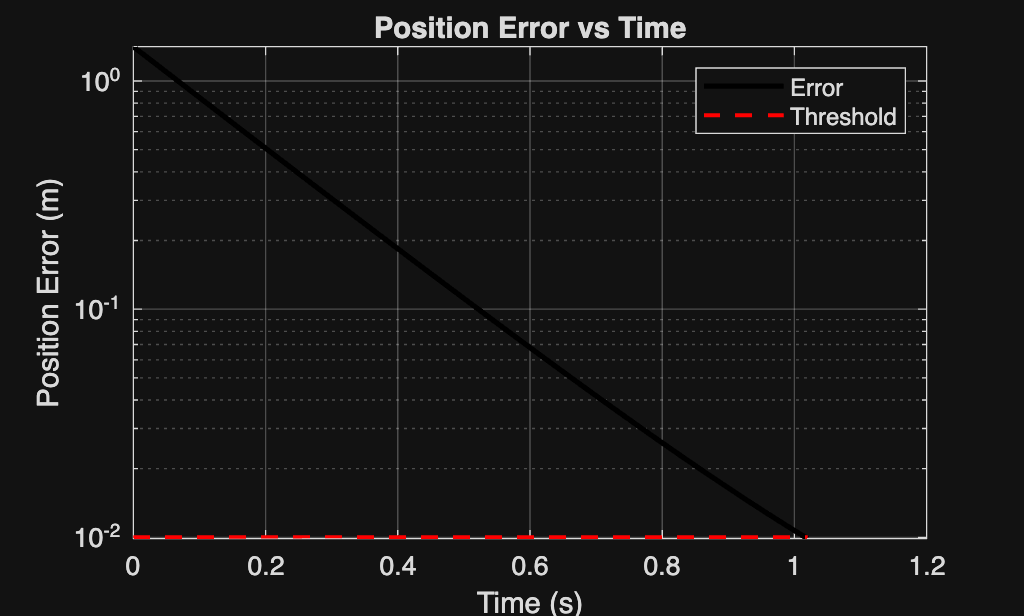


% Figure 4: Position error
figure('Name', 'Position Error');
semilogy(time, error_history, 'k-', 'LineWidth', 2);
hold on;
semilogy([time(1), time(end)], [epsilon, epsilon], 'r--', 'LineWidth', 1.5);
grid on;
xlabel('Time (s)'); ylabel('Position Error (m)');
title('Position Error vs Time');
legend('Error', 'Threshold');
hold off;


fprintf('\nAll plots generated\n');


All plots generated



%% Helper Function
function plot_robot(l1, l2, theta1, theta2, p_desired)
    % Joint positions
    x0 = 0; y0 = 0;
    x1 = l1 * cos(theta1);
    y1 = l1 * sin(theta1);
    x2 = x1 + l2 * cos(theta1 + theta2);
    y2 = y1 + l2 * sin(theta1 + theta2);
    
    hold on;
    
    % Links
    plot([x0, x1], [y0, y1], 'r-', 'LineWidth', 3);
    plot([x1, x2], [y1, y2], 'b-', 'LineWidth', 3);
    
    % Joints
    plot(x0, y0, 'ko', 'MarkerSize', 10, 'MarkerFaceColor', 'k');
    plot(x1, y1, 'mo', 'MarkerSize', 10, 'MarkerFaceColor', 'm');
    plot(x2, y2, 'go', 'MarkerSize', 12, 'MarkerFaceColor', 'g');
    
    % Desired position
    plot(p_desired(1), p_desired(2), 'r*', 'MarkerSize', 15, 'LineWidth', 2);
    
    % Labels
    text(x0-0.1, y0-0.2, 'F_W');
    text(x2+0.1, y2+0.1, 't^W_E');
    
    % Angle annotations
    r_arc = 0.3;
    if abs(theta1) > 0.01
        angle_arc = linspace(0, theta1, 20);
        plot(r_arc*cos(angle_arc), r_arc*sin(angle_arc), 'k--');
        text(0.4*cos(theta1/2), 0.4*sin(theta1/2), '\theta_1');
    end
    
    if abs(theta2) > 0.01
        angle_arc = linspace(theta1, theta1+theta2, 20);
        plot(x1 + r_arc*cos(angle_arc), y1 + r_arc*sin(angle_arc), 'k--');
        text(x1 + 0.4*cos(theta1+theta2/2), y1 + 0.4*sin(theta1+theta2/2), '\theta_2');
    end
    
    axis equal; grid on;
    xlabel('x (m)'); ylabel('y (m)');
    
    max_reach = l1 + l2;
    xlim([-max_reach*0.3, max_reach*1.2]);
    ylim([-max_reach*0.3, max_reach*1.2]);
    hold off;
end